# Introduction to Drones - 22AIE448

**3D Mapping using a Monocular Camera and Control by Visual-Inertial Odometry (VIO)**

Group CD2 : Ravishanmugam K, Ishwarya Murugesan, Aparna Bharani, Cibikumar B, Akhilan S

School of Artificial Intelligence, Amrita Vishwa Vidyapeetham

**Toy model 3 - Model 1, Part 1 : how the drone moves (blocks 1, 2 and 3)**

Run this file with the folder `toy_model3` as the current folder (it uses `DroneLib.m`).

clearvars
clear all
ready = true;
PUBLISH = not(ready);   % make this PUBLISH = ready; to export the file as PDF

clearvars -except PUBLISH ready

## Model 1 - the flow

Model 1 is the loop that flies the drone. It is built from 8 blocks.

- **Nonlinear dynamics** - Newton and Euler laws of the drone  *(this file)*

- **Linearization** - first order Taylor series, Jacobians $A$ and $B$  *(this file)*

- **Local error dynamics** - how a small error grows, $F = I + A\Delta t$  *(this file)*

- **Error-state EKF** - fuse camera (VIO) and IMU  *(M1_2_Error_State_EKF)*

- **Position control** - outer loop  *(M1_3_SO3_Control_Closed_Loop)*

- **Force and attitude** - which way to lean  *(M1_3)*

- **SO(3) attitude control** - inner loop  *(M1_3)*

- **Control allocation** - four motor speeds  *(M1_3)*

## Block 1 - Nonlinear dynamics of the quadrotor

The drone is one rigid body of mass $m$ and inertia $J$. The four rotors push with a total thrust $T$ along the drone's own $z$ axis and twist it with a torque $\tau$. The state is position $p$, velocity $v$, attitude (rotation matrix) $R$ and body angular velocity $\omega$.


$$\dot{p} = v \qquad \rightarrow (1)$$



$$\dot{v} = g + \frac{T}{m} R\, e_3 \qquad \rightarrow (2)$$



$$\dot{R} = R\,[\omega]_{\times} \qquad \rightarrow (3)$$



$$\dot{\omega} = J^{-1}\left(\tau - \omega \times J\omega\right) \qquad \rightarrow (4)$$


$g = [0,\,0,\,-9.81]^T$ (ENU world frame, $z$ up), $e_3 = [0,\,0,\,1]^T$ and $[\omega]_{\times}$ is the skew matrix with $[\omega]_{\times} b = \omega \times b$.

- (1) velocity is the rate of change of position.

- (2) Newton: $m\dot{v}$ = gravity + thrust. The thrust $T e_3$ is written in the body; $R$ turns it into the world frame.

- (3) a gyroscope measures $\omega$ in the body; this is how it turns $R$.

- (4) Euler: torque changes the spin. $\omega \times J\omega$ is the gyroscopic coupling.

Parameters (from `drones_controller/config/controller.yaml`):

P = DroneLib.params();
m = P.m      % mass [kg]

m = 1.5000

J = P.J      % inertia [kg m^2]

J =     0.0200         0         0
         0    0.0200         0
         0         0    0.0400


**Toy example 1 : hover.** $R = I$, $\omega = 0$, $T = mg = 14.715$ N, $\tau = 0$.


$$\dot{v} = \left[\begin{array}{c} 0\\ 0\\ -9.81 \end{array}\right] + \frac{14.715}{1.5}\left[\begin{array}{c} 0\\ 0\\ 1 \end{array}\right] = \left[\begin{array}{c} 0\\ 0\\ 0 \end{array}\right]$$


x_hover = DroneLib.pack([0;0;2], [0;0;0], eye(3), [0;0;0]);
u_hover = [m*P.g0; 0; 0; 0]          % [T; tau_x; tau_y; tau_z]

u_hover =    14.7150
         0
         0
         0


xdot  = DroneLib.f(x_hover, u_hover, P);
v_dot = xdot(4:6)'                   % zero : the drone hangs still

v_dot =      0     0     0


**Toy example 2 : 10 degree roll with hover thrust.** $R e_3 = [0,\, -\sin 10^\circ,\, \cos 10^\circ]^T$


$$\dot{v} = 9.81\left[\begin{array}{c} 0\\ -\sin 10^\circ\\ \cos 10^\circ - 1 \end{array}\right] = \left[\begin{array}{c} 0\\ -1.7035\\ -0.1490 \end{array}\right] \textrm{ m/s}^2$$


It slides sideways and sinks, because only $\cos 10^\circ = 98.5\%$ of the thrust still holds it up.

R10   = DroneLib.expSO3([deg2rad(10); 0; 0]);     % rotation of 10 deg about x
x_10  = DroneLib.pack([0;0;2], [0;0;0], R10, [0;0;0]);
xdot  = DroneLib.f(x_10, u_hover, P);
v_dot = xdot(4:6)'

v_dot =          0   -1.7035   -0.1490


**Toy example 3 : gyroscopic coupling.** $\omega = [1,\,0,\,1]^T$ rad/s and no torque.


$$J\omega = [0.02,\,0,\,0.04]^T,\quad \omega \times J\omega = [0,\,-0.02,\,0]^T,\quad \dot{\omega} = J^{-1}[0,\,0.02,\,0]^T = [0,\,1,\,0]^T$$


Spinning about $x$ and $z$ together starts a spin about $y$ without any torque.

w = [1; 0; 1];
w_dot = (J \ (zeros(3,1) - cross(w, J*w)))'

w_dot =      0     1     0


**Open loop flight using the inbuilt function ode45**

Hover thrust plus a tiny roll torque of 0.01 N m for only 0.1 s. Nobody corrects it.

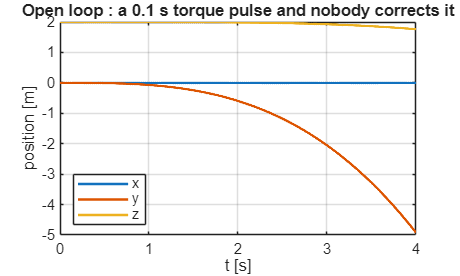

u_of_t = @(t) u_hover + [0; 0.01*(t < 0.1); 0; 0];
odefun = @(t, x) DroneLib.f(x, u_of_t(t), P);
[t, X] = ode45(odefun, [0 4], x_hover, odeset('MaxStep', 0.01));
figure
plot(t, X(:,1), t, X(:,2), t, X(:,3), LineWidth=1.5); grid on
xlabel("t [s]"); ylabel("position [m]"); legend("x","y","z", Location="southwest")
title("Open loop : a 0.1 s torque pulse and nobody corrects it")

drift = norm(X(end,1:3)' - [0;0;2])     % metres after 4 s

drift = 4.9296

A drone is **unstable on its own**. It needs an estimate of its state (block 4) and feedback control (blocks 5 to 8).

## Block 2 - Linearization (first order Taylor series)

From the Taylor series of a function of many variables, around an operating point $(\hat{x},\hat{u})$:


$$f(x,u) \approx f(\hat{x},\hat{u}) + A\,\delta x + B\,\delta u, \qquad A = \frac{\partial f}{\partial x}\Big|_{\hat{x},\hat{u}}, \quad B = \frac{\partial f}{\partial u}\Big|_{\hat{x},\hat{u}}$$


The error state has 12 numbers (the attitude error is a small rotation vector $\delta\theta$ with $R = \hat{R}\,\textrm{Exp}(\delta\theta)$):


$$\delta x = \left[\begin{array}{c} \delta p\\ \delta v\\ \delta\theta\\ \delta\omega \end{array}\right] = \left[\begin{array}{c} p - \hat{p}\\ v - \hat{v}\\ \textrm{Log}(\hat{R}^T R)\\ \omega - \hat{\omega} \end{array}\right], \qquad \delta u = \left[\begin{array}{c} \delta T\\ \delta\tau \end{array}\right]$$


Put $R \approx \hat{R}(I + [\delta\theta]_\times)$, $T = \hat{T} + \delta T$, ... into (1)-(4) and keep only first order terms:


$$\delta\dot{p} = \delta v$$



$$\delta\dot{v} = -\frac{\hat{T}}{m}\hat{R}[e_3]_\times\,\delta\theta + \frac{1}{m}\hat{R}e_3\,\delta T$$



$$\delta\dot{\theta} = -[\hat{\omega}]_\times\,\delta\theta + \delta\omega$$



$$\delta\dot{\omega} = J^{-1}\left([J\hat{\omega}]_\times - [\hat{\omega}]_\times J\right)\delta\omega + J^{-1}\delta\tau$$



$$A = \left[\begin{array}{cccc} 0 & I & 0 & 0\\ 0 & 0 & -\frac{\hat{T}}{m}\hat{R}[e_3]_\times & 0\\ 0 & 0 & -[\hat{\omega}]_\times & I\\ 0 & 0 & 0 & J^{-1}([J\hat{\omega}]_\times - [\hat{\omega}]_\times J) \end{array}\right], \qquad B = \left[\begin{array}{cc} 0 & 0\\ \frac{1}{m}\hat{R}e_3 & 0\\ 0 & 0\\ 0 & J^{-1} \end{array}\right]$$


At hover ($\hat{R} = I$, $\hat{\omega} = 0$, $\hat{T} = mg$):

[A, B] = DroneLib.jacobians(x_hover, u_hover, P);
A_v_theta = A(4:6, 7:9)      % a pitch error pushes along +x, a roll error along -y

A_v_theta =          0    9.8100         0
   -9.8100         0         0
         0         0         0


B_v_T     = B(4:6, 1)'       % extra thrust only changes vertical acceleration (1/m)

B_v_T =          0         0    0.6667


B_w_tau   = B(10:12, 2:4)    % torque -> angular acceleration (J^-1)

B_w_tau =     50     0     0
     0    50     0
     0     0    25


**Check the derivatives numerically** at a tilted, spinning, accelerating state (central differences, $\partial f/\partial x_j \approx (f(x + h e_j) - f(x - h e_j))/2h$):

xs = DroneLib.pack([0.5;-1;2], [1;0.5;-0.2], DroneLib.expSO3([0.3;-0.2;0.5]), [0.4;-0.3;0.6]);
us = [16; 0.02; -0.01; 0.005];
[As, Bs] = DroneLib.jacobians(xs, us, P);
h = 1e-6;
Anum = zeros(6,6);  Bnum = zeros(6,4);
for j = 1:6                                   % columns: dtheta (3) and domega (3)
    e = zeros(12,1); e(6+j) = h;
    fp = DroneLib.f(DroneLib.boxplus(xs, e), us, P);
    fm = DroneLib.f(DroneLib.boxplus(xs, -e), us, P);
    Anum(:,j) = ([fp(4:6); fp(16:18)] - [fm(4:6); fm(16:18)])/(2*h);
end
for j = 1:4
    e = zeros(4,1); e(j) = h;
    fp = DroneLib.f(xs, us + e, P);  fm = DroneLib.f(xs, us - e, P);
    Bnum(:,j) = ([fp(4:6); fp(16:18)] - [fm(4:6); fm(16:18)])/(2*h);
end
err_A = max(abs(Anum - As([4:6 10:12], 7:12)), [], 'all')

err_A = 4.8827e-10

err_B = max(abs(Bnum - Bs([4:6 10:12], :)), [], 'all')

err_B = 6.8235e-10

**How good is first order?** Pitch the hovering drone by $\theta$. The linear model says $\dot{v}_x = g\,\theta$, the truth is $g\sin\theta$.

theta_deg = [1; 2.87; 10; 20; 28.65];
lin       = P.g0*deg2rad(theta_deg);
truth     = P.g0*sin(deg2rad(theta_deg));
error_pct = 100*(lin - truth)./truth;
table(theta_deg, lin, truth, error_pct)

ans = 5×4 table
    theta_deg      lin       truth     error_pct
    _________    _______    _______    _________

          1      0.17122    0.17121    0.0050771
       2.87      0.49139    0.49119     0.041831
         10       1.7122     1.7035      0.50951
         20       3.4243     3.3552         2.06
      28.65       4.9054     4.7035       4.2921


Below 10 degrees of tilt (normal flight) the error is below 0.5 %. This is why the EKF (block 4) and Model 2 can use a linear model.

## Block 3 - Local error dynamics

Subtract the model of the estimate from the model of the truth:


$$\delta\dot{x} = f(x,u) - f(\hat{x},\hat{u}) \approx A\,\delta x + B\,\delta u$$


Over one sample $\Delta t$ (input held constant):


$$\delta x_{k+1} = F\,\delta x_k + G\,\delta u_k, \qquad F = e^{A\Delta t} \approx I + A\Delta t, \qquad G \approx B\Delta t$$


dt = 0.01;                          % EKF / IMU sample time [s]
F  = eye(12) + A*dt;
max_F_error = max(abs(F - expm(A*dt)), [], 'all')   % size of the dropped (A dt)^2/2

max_F_error = 4.9050e-04

eig_A = eig(A)'                                       % all zero at hover

eig_A =      0     0     0     0     0     0     0     0     0     0     0     0


All eigenvalues of $A$ are 0: rate error $\rightarrow$ attitude error $\rightarrow$ velocity error $\rightarrow$ position error is a chain of 4 integrators. A constant roll-rate error $\delta\omega_x$ gives


$$\delta y(t) = -\frac{g\,\delta\omega_x\,t^3}{6} \qquad (\delta\omega_x = 0.01\textrm{ rad/s},\ t = 2\textrm{ s} \Rightarrow \delta y = -0.1308\textrm{ m})$$


**Linear prediction versus the nonlinear truth** for a small (2 deg) and a large (30 deg) initial roll error:

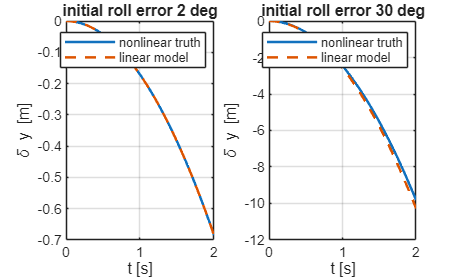

 2 deg : linear model is off by 0.02 % after 2 s
30 deg : linear model is off by 4.72 % after 2 s


T_end = 2;  n = round(T_end/dt);  tt = (0:n)*dt;
cases = [2 30];                                       % initial roll error [deg]
figure
for c = 1:2
    dx0 = [0.1;0;0; 0;0;0; deg2rad(cases(c));0;0; 0;0;0.2];
    x  = DroneLib.boxplus(x_hover, dx0);
    Y_true = zeros(1, n+1);  Y_lin = zeros(1, n+1);
    for k = 1:n+1
        dx_true = DroneLib.boxminus(x, x_hover);     % true error
        dx_lin  = expm(A*tt(k))*dx0;                 % linear model
        Y_true(k) = dx_true(2);  Y_lin(k) = dx_lin(2);
        x = DroneLib.rk4(x, u_hover, dt, P);
    end
    subplot(1,2,c)
    plot(tt, Y_true, tt, Y_lin, '--', LineWidth=1.5); grid on
    xlabel("t [s]"); ylabel("\delta y [m]"); legend("nonlinear truth","linear model")
    title(sprintf("initial roll error %d deg", cases(c)))
    fprintf("%2d deg : linear model is off by %.2f %% after 2 s\n", ...
            cases(c), 100*abs(Y_lin(end) - Y_true(end))/abs(Y_true(end)));
end

The linear model is **local**: excellent for small errors, poor for large ones. The EKF only ever propagates the small difference between estimate and truth, which the camera and the IMU keep small. That is why it is called an **error-state** filter.

**In the real drone:** equations (1)-(4) are solved by Gazebo for the Iris quadrotor and ArduPilot SITL plays the flight computer. Our ROS 2 node only reads the result on `/ap/v1/pose/filtered` and `/ap/v1/twist/filtered`.

if(PUBLISH == ready)
    mlxfile = matlab.desktop.editor.getActive().Filename;
    [folder, name, ext] = fileparts(mlxfile);
    outfilepdf = fullfile(folder, 'pdf', [name, ext, '.pdf']);
    export(mlxfile, outfilepdf);
    if ispc
        winopen(outfilepdf);
    elseif ismac
        system(['open ' char(outfilepdf)]);
    else
        system("env -u LD_LIBRARY_PATH xdg-open '" + outfilepdf + "' &");
    end
end